This is one example of using SEIV and SEIVD model to fit community model

First load the data and the parameters:

% import data
load('./../data/data/qpcr','data'); % qpcr data
load('./../data/data/parameters_example','pars'); % parameters without nans
pars1 = pars;
load('./../data/data/parameters'); % true parameter set with nans
addpath(genpath('./../'))

Next fix the type of model.

pars.NE = 10*(pars.M == 1);
pars.NE(1,2) = 63;
pars.NE(2,1) = 75;
pars.NE(2,2) = 69;
pars.NE(2,3) = 70;
pars.NE(3,3) = 68;
pars.NE(4,4) = 75;
pars.NE(4,5) = 98;
pars.NE(5,4) = 87;
pars.NE(5,5) = 109;

pars1.NE = pars.NE;


max_NE = round(max(max(pars.NE)));
model = SEIV_diff_NE(5,5,max_NE);
model.host_growth = 0;
model.viral_decay = 0;
model.viral_adsorb = 0;
model.lysis_reset = 0;
model.debris_inhib = 2;  %only debris based inhibition is used.


include lysis inhibition methods:

if (model.debris_inhib == 1 || model.debris_inhib == 2 || model.debris_inhib == 3)
    %pars1.Dc = 1e8;
    pars1.Dc = 4389100;
    %pars1.Dc = 3.9e6;
    pars_labels.Dc = "";
    pars_units.Dc = "1/ml";
end


% controlling lysis 
if model.lysis_reset == 1
    pars1.epsilon_reset = 0.01;
    pars_labels.epsilon_reset = "";
    pars_units.epsilon_reset = "";
end

List of parameters (shown for example, this is before convergence)

pars1.beta = [0 332.5199 0 0 0; 285.8763  389.8026  285.1307 0 0; 0 0 81.5296 0 0; 0 0 0 172.3908 115.6997; 0 0 0 421.0652  84.0754];
pars1.phi = 1.0e-06 *[0 0.0779 0 0 0; 0.1471 0.0590 0.0526 0 0; 0 0 0.0651 0 0; 0 0 0 0.0014 0.0260; 0 0 0 0.0123 0.0012];
pars1.epsilon = [1.4320    0.7033    1.0714    1.0794    0.8978    1.2552    1.1261    1.3579    1.3952    1.0795];
  pars1.r = [ 0.1075;
    0.2900;
    0.0485;
    0.4375;
    0.4088];


pars1.eta = [ 0    0.2101         0         0         0;
    0.2122    0.1954    0.1917         0         0;
         0         0    0.2437         0         0;
         0         0         0    0.1163    0.2693;
         0         0         0    0.5219    0.0525];




%pars1.r = [9.9527e-02   8.8231e-02   1.6471e-02   3.3874e-01   4.8873e-01]';
%pars1.beta = [0 285 0 0 0; 316  426  261 0 0; 0 0 86 0 0; 0 0 0 172.3908 395; 0 0 0 143 14.3];



pars1.tau(pars1.tau>0) = 1./pars1.eta(pars1.tau>0);


pars.beta = pars1.beta;
pars.phi = pars1.phi;
pars.epsilon = pars1.epsilon;
pars.r = pars1.r;
pars.eta = pars1.eta;
pars.tau = pars1.tau;
pars.Dc = pars1.Dc;

Simulate time series based on the parameters:

tvec = 0:0.05:15.75; % for better viz
[t1,S1,V1,D1] = simulate_ode(model,pars1,tvec,pars1.S0,pars1.V0); % initial parameter set

hosts --- SEIVD

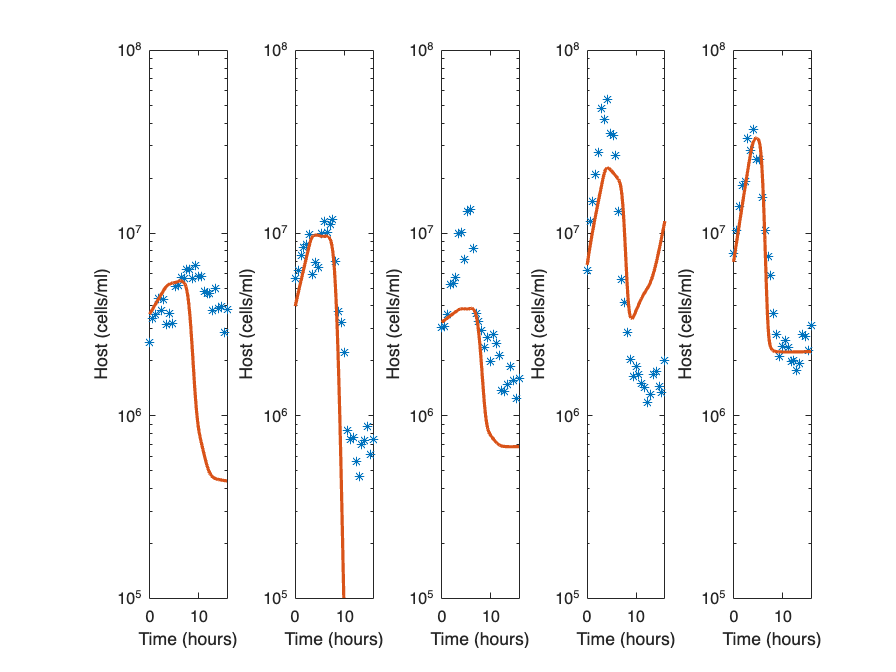

fig1 = figure;
%han=axes(fig1,'visible','off'); 
%title(han,'SEIVD');
for i=1:model.NH
    subplot(1,5,i)
plot(data.xdata,data.ydata(:,i),'*');hold on;plot(t1,S1(:,i),'-',LineWidth=2); %microbes
xlabel('Time (hours)');ylabel('Host (cells/ml)');set(gca,'Yscale','log'); ylim([1e5 1e8])
%title(['Points are from averaged experimental datasets, line is from simulated SEIV model' ...
    %' (N_E=10)'])
end

virus -- SEIVD

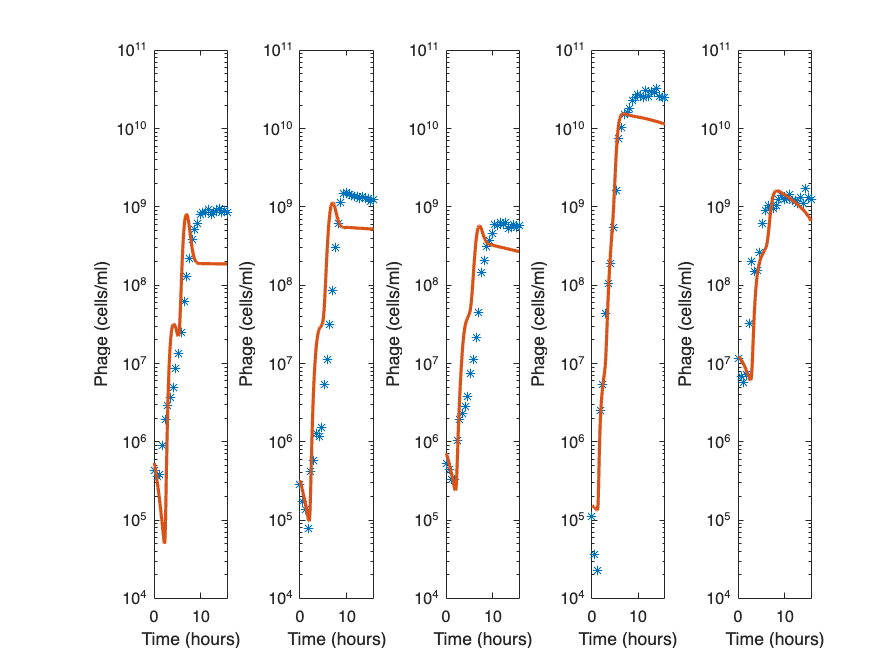

fig2 = figure;
for i=1:model.NV
    subplot(1,5,i)
plot(data.xdata,data.ydata(:,i+5),'*');hold on;plot(t1,V1(:,i),'-',LineWidth=2); %virus
xlabel('Time (hours)');ylabel('Phage (cells/ml)');set(gca,'Yscale','log');ylim([1e4 1e11])
%title('Points are from averaged experimental datasets, line is from simulated SEIV model (N_E=10)')
end

Now showing for SEIV model,

model.debris_inhib = 0;  %only debris based inhibition is used.
pars1.Dc = 0;
pars.Dc = 0;

tvec = 0:0.05:15.75; % for better viz
[t1,S1,V1,D1] = simulate_ode(model,pars1,tvec,pars1.S0,pars1.V0); % initial parameter set

hosts -- SEIV

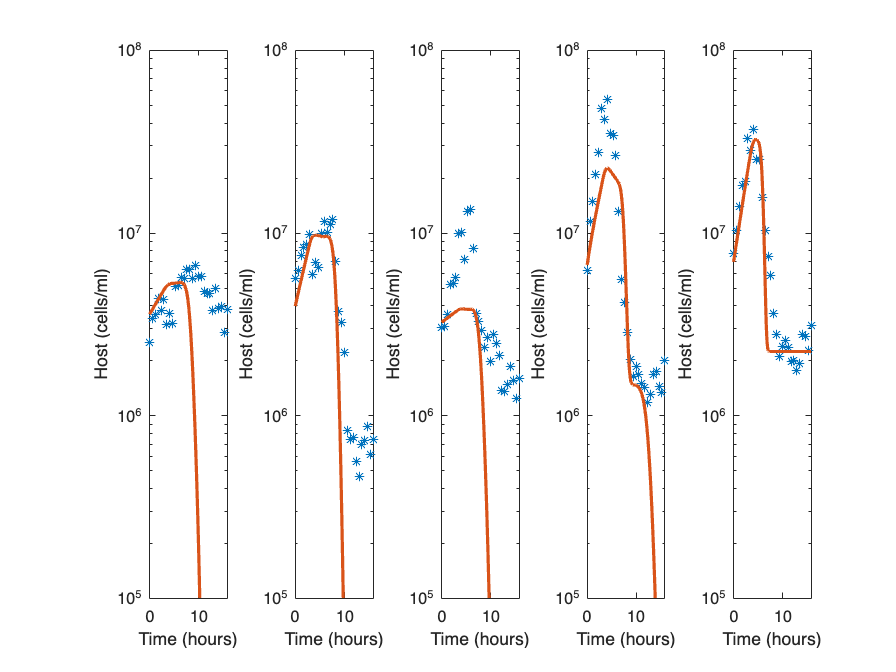

fig3 = figure;

for i=1:model.NH
    subplot(1,5,i)
plot(data.xdata,data.ydata(:,i),'*');hold on;plot(t1,S1(:,i),'-',LineWidth=2); %microbes
xlabel('Time (hours)');ylabel('Host (cells/ml)');set(gca,'Yscale','log'); ylim([1e5 1e8])
%title(['Points are from averaged experimental datasets, line is from simulated SEIV model' ...
    %' (N_E=10)'])
end

virus -- SEIV

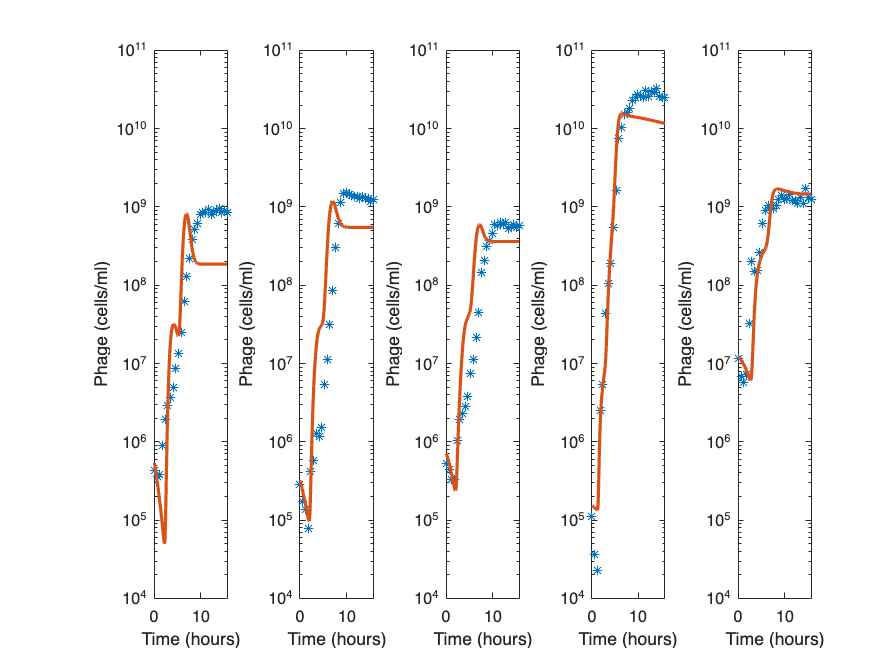

fig4 = figure;
for i=1:model.NV
    subplot(1,5,i)
plot(data.xdata,data.ydata(:,i+5),'*');hold on;plot(t1,V1(:,i),'-',LineWidth=2); %virus
xlabel('Time (hours)');ylabel('Phage (cells/ml)');set(gca,'Yscale','log');ylim([1e4 1e11])
%title('Points are from averaged experimental datasets, line is from simulated SEIV model (N_E=10)')
end